# **Численные методы в СПб АУ РАН - Часть 2**

## **Задание по практике №4**

Кузьмичев Артём, 4 курс

## **№9 (упражнения к разделу 9.4)**

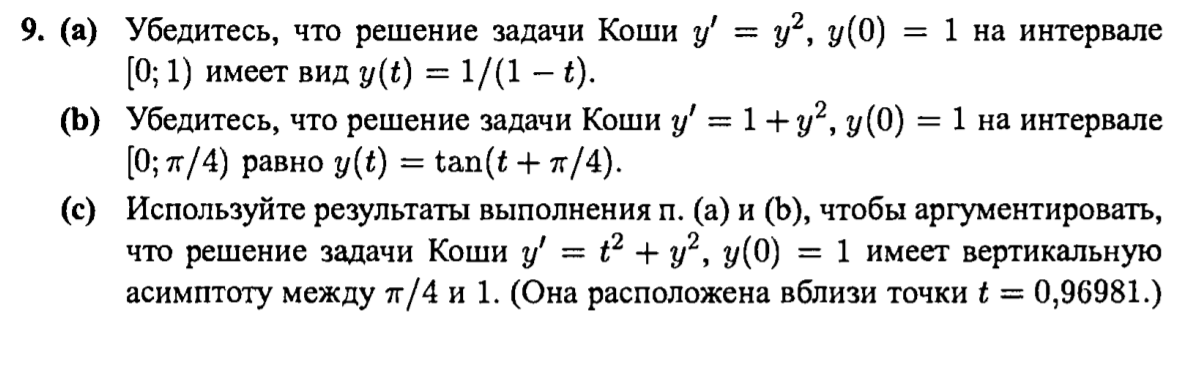

**Пункт (а)**

Проверим выполнение дифференциального уравнения:


$${y^{\prime } }_a \left(t\right)=\frac{d}{\textrm{dt}}\left(\frac{1}{1-t}\right)=-\frac{{\left(1-t\right)}^{\prime } }{{\left(1-t\right)}^2 }=\frac{1}{{\left(1-t\right)}^2 }={y\left(t\right)}^2$$


Проверим выполнение условия:


$$y_a \left(0\right)=\frac{1}{1-0}=1$$


**Пункт (б)**

Проверим выполнение дифференциального уравнения, применив тригонометрическое тождество. 


$${y^{\prime } }_б \left(t\right)=\frac{d}{\textrm{dt}}\left(\tan \left(t+\frac{\pi }{4}\right)\right)=\frac{1}{\cos^2 \left(t+\frac{\pi }{4}\right)}={1+\tan }^2 \left(t+\frac{\pi }{4}\right)=1+{y\left(t\right)}^2$$


Проверим выполнение условия:


$$y_б \left(0\right)=\tan \left(0+\frac{\pi }{4}\right)=\tan \left(\frac{\pi }{4}\right)=1$$


**Пункт (в)**

Нетрудно заметить, что на интервале $\left\lbrack 0;1\right\rbrack$ правые части уравенений из пунктов (а) и (б) являются соответственно нижней и верхней оценками правой части $y^{\prime } =t^2 +y^2$


$${y^2 \le t}^2 +y^2 \le {1+y}^2$$


Откуда:


$$\frac{dy_a \left(t\right)}{\textrm{dt}}\le \frac{dy_в \left(t\right)}{\textrm{dt}}\le \frac{dy_б \left(t\right)}{\textrm{dt}}$$


Интегрируя:


$$\int_0^t \frac{dy_a \left(t\right)}{\textrm{dt}}\textrm{dt}\le \int_0^t \frac{dy_в \left(t\right)}{\textrm{dt}}dt\le \int_0^t \frac{dy_б \left(t\right)}{\textrm{dt}}dt$$


С учётом того, что решение из пункта а: $y_a \left(t\right)=\frac{1}{1-t}=\int_0^t \frac{dy_a \left(t\right)}{\textrm{dt}}dt$имеет вертикальную асимптоту в $t=1$, а решение из пункта б: $y_б \left(t\right)=\tan \left(t+\frac{\pi }{4}\right)=\int_0^t \frac{dy_б \left(t\right)}{\textrm{dt}}dt$ имеет вертикальную асимптоту в $t=\frac{\pi }{4}$ понятно, что решение задачи Коши $y_в \left(t\right)$, зажатое между ними, также должно иметь вертикальную асимптоту где-то на промежутке между $t=\frac{\pi }{4}$, $t=1$, **что и требовалось доказать**

Посмотрим, как решает такую задачу сам Matlab:

syms y1(t) y2Sol y3(t) y2(t)
eqn = diff(y2,t) == t^2+y2^2;
cond = y2(0) == 1;
y2Sol(t) = dsolve(eqn,cond)

$$y2Sol(t) = \begin{array}{l} -\frac{t\,\left(\pi \,\sigma_{2}-\sigma_{1}\,\sigma_{2}+\sigma_{1}\,Y_{-\frac{3}{4}}\left(\frac{t^{2}}{2}\right)\right)}{\pi \,\sigma_{3}-\sigma_{1}\,\sigma_{3}+\sigma_{1}\,Y_{\frac{1}{4}}\left(\frac{t^{2}}{2}\right)}\\ \mathrm{where}\\ \sigma_{1}={\Gamma (\frac{3}{4})}^{2}\\ \sigma_{2}=J_{-\frac{3}{4}}\left(\frac{t^{2}}{2}\right)\\ \sigma_{3}=J_{\frac{1}{4}}\left(\frac{t^{2}}{2}\right) \end{array}$$

Установим границы, просто чтобы было получше видно:

lb = 0.7;
rb = 1;

И построим все 3 функции на одном графике:

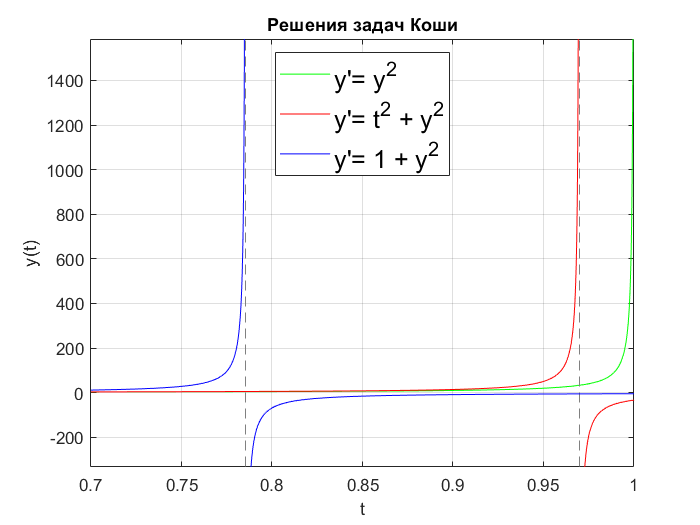

syms t
y1(t) = 1/(1-t);
y3(t) = tan(t+pi/4);
figure
fplot(y1(t), [lb rb], "g");
grid on
title("Решения задач Коши");
xlabel("t")
ylabel("y(t)")
hold on
fplot(y2Sol, [lb rb], "r");
fplot(y3(t), [lb rb],"b");
legend("y'= y^2","y'= t^2 + y^2","y'= 1 + y^2", 'Location','north','FontSize',15)